# Plot 7.3

data = ref_pos.Data

data = data(:,:,1) =

    1.5190
   -2.6522
    1.0000


data(:,:,2) =

    1.5190
   -2.6522
    1.0000


data(:,:,3) =

    1.5191
   -2.6522
    1.0000


data(:,:,4) =

    1.5191
   -2.6522
    1.0000


data(:,:,5) =

    1.5193
   -2.6523
    1.0000


data(:,:,6) =

    1.5195
   -2.6524
    1.0001


data(:,:,7) =

    1.5199
   -2.6526
    1.0001


data(:,:,8) =

    1.5203
   -2.6528
    1.0002


data(:,:,9) =

    1.5210
   -2.6532
    1.0002


data(:,:,10) =

    1.5218
   -2.6536
    1.0003


data(:,:,11) =

    1.5228
   -2.6541
    1.0004


data(:,:,12) =

    1.5241
   -2.6548
    1.0006


data(:,:,13) =

    1.5255
   -2.6556
    1.0007


data(:,:,14) =

    1.5272
   -2.6565
    1.0009


data(:,:,15) =

    1.5292
   -2.6576
    1.0012


data(:,:,16) =

    1.5315
   -2.6588
    1.0014


data(:,:,17) =

    1.5341
   -2.6602
    1.0017


data(:,:,18) =

    1.5370
   -2.6618
    1.0020


data(:,:,19) =

    1.5402
   -2.6635
    1.0024


data(:,:,20) =

    1.5438
   -2.

x = data(1,:,:);
y = data(2,:,:);
z = data(3,:,:);
xx = x(:)

xx =     1.5190
    1.5190
    1.5191
    1.5191
    1.5193
    1.5195
    1.5199
    1.5203
    1.5210
    1.5218


yy = y(:)

yy =    -2.6522
   -2.6522
   -2.6522
   -2.6522
   -2.6523
   -2.6524
   -2.6526
   -2.6528
   -2.6532
   -2.6536


zz = z(:)

zz =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0001
    1.0001
    1.0002
    1.0002
    1.0003


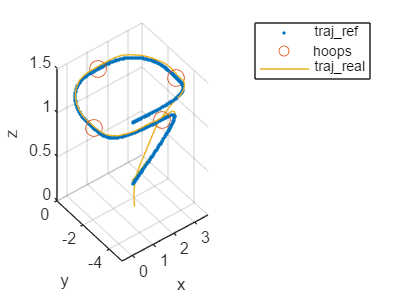

hoops_x = [p_h1(1), p_h2(1), p_h3(1), p_h4(1)];
hoops_y = [p_h1(2), p_h2(2), p_h3(2), p_h4(2)];
hoops_z = [p_h1(3), p_h2(3), p_h3(3), p_h4(3)];
clf
figure
% plot3(xx, yy, zz)
scatter3(xx, yy, zz,'.')
hold on
scatter3(hoops_x, hoops_y, hoops_z, 100, 'o')
plot3(pos.Data(:,1), pos.Data(:,2), pos.Data(:,3))
legend('traj\_ref','hoops', 'traj\_real')
xlabel("x")
ylabel('y')
zlabel('z')

## Plot 7.2

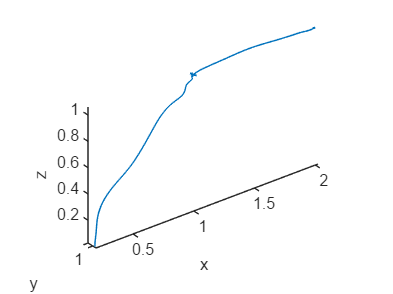

figure
plot3(pos.Data(:,1), pos.Data(:,2), pos.Data(:,3))
axis equal
xlabel("x")
ylabel("y")
zlabel("z")


data = ref_pos.Data

data = data(:,:,1) =

     1
     1
     1


data(:,:,2) =

     1
     1
     1


data(:,:,3) =

     1
     1
     1


data(:,:,4) =

     1
     1
     1


data(:,:,5) =

     1
     1
     1


data(:,:,6) =

     1
     1
     1


data(:,:,7) =

     1
     1
     1


data(:,:,8) =

     1
     1
     1


data(:,:,9) =

     1
     1
     1


data(:,:,10) =

     1
     1
     1


data(:,:,11) =

     1
     1
     1


data(:,:,12) =

     1
     1
     1


data(:,:,13) =

     1
     1
     1


data(:,:,14) =

     1
     1
     1


data(:,:,15) =

     1
     1
     1


data(:,:,16) =

     1
     1
     1


data(:,:,17) =

     1
     1
     1


data(:,:,18) =

     1
     1
     1


data(:,:,19) =

     1
     1
     1


data(:,:,20) =

     1
     1
     1


data(:,:,21) =

     1
     1
     1


data(:,:,22) =

     1
     1
     1


data(:,:,23) =

     1
     1
     1


data(:,:,24) =

     1
     1
     1


data(:,:,25) =

     1
     1
     1


data(:,:,26) =

     1
    

x = data(1,:,:);
y = data(2,:,:);
z = data(3,:,:);
xx = x(:);

xx =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


yy = y(:);

yy =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


zz = z(:);

zz =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


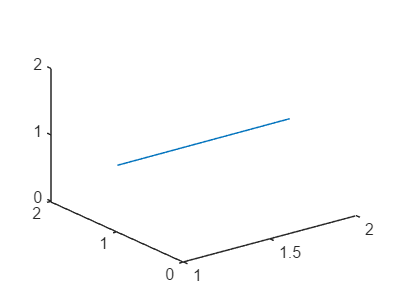

figure
plot3(xx, yy, zz)

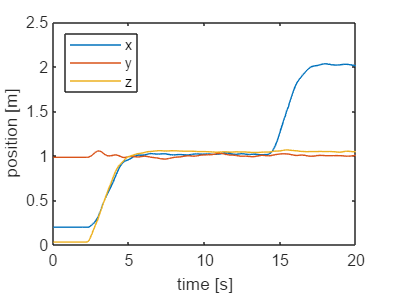

time = pos.Time;
clf
plot(time, pos.Data(:,1))
hold on
plot(time, pos.Data(:,2))
plot(time, pos.Data(:,3))
legend("x",'y','z','Location','northwest')
xlabel('time [s]')
ylabel('position [m]')

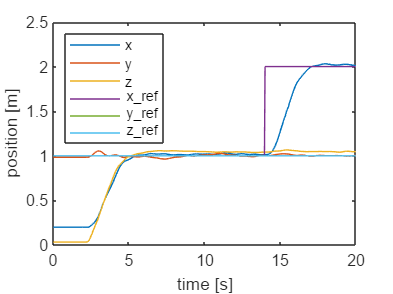

clf
plot(time, pos.Data(:,1))
hold on
plot(time, pos.Data(:,2))
plot(time, pos.Data(:,3))
plot(time,xx)
plot(time,yy)
plot(time,zz)
legend("x",'y','z','x\_ref', 'y\_ref', 'z\_ref','Location','northwest')
xlabel('time [s]')
ylabel('position [m]')

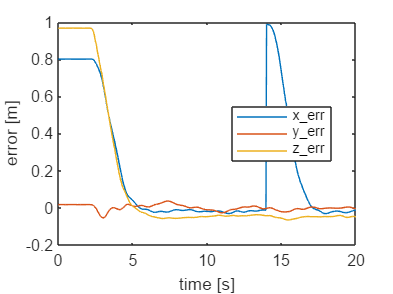

hold off

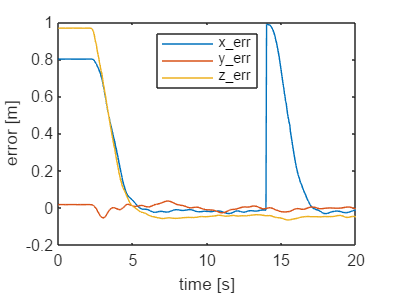

x_err = xx - pos.Data(:,1);
y_err = yy - pos.Data(:,2);
z_err = zz - pos.Data(:,3);
clf
figure
plot(time, x_err)
hold on
plot(time, y_err)
plot(time,z_err)
legend("x\_err",'y\_err','z\_err','Location','north')
xlabel('time [s]')
ylabel('error [m]')